GSR_raw = BitalinoGSR;

% Identifikasi nilai minimum dalam data GSR
min_GSR = min(GSR_raw);

% Tentukan offset
if min_GSR < 0
    offset_correction = abs(min_GSR) + 1; % Tambahkan 1 μS sebagai margin
    fprintf('Nilai minimum GSR: %.2f μS\n', min_GSR);
    fprintf('Offset yang ditambahkan: %.2f μS\n', offset_correction);
    
    % Terapkan offset correction
    GSR_corrected = GSR_raw + offset_correction;
else
    fprintf('Data GSR sudah non-negatif. Tidak perlu offset correction.\n');
    GSR_corrected = GSR_raw;
end

Nilai minimum GSR: -4.73 μS


Offset yang ditambahkan: 5.73 μS



% Verifikasi setelah offset correction
min_corrected = min(GSR_corrected);
fprintf('Nilai minimum setelah offset correction: %.2f μS\n', min_corrected);

Nilai minimum setelah offset correction: 1.00 μS


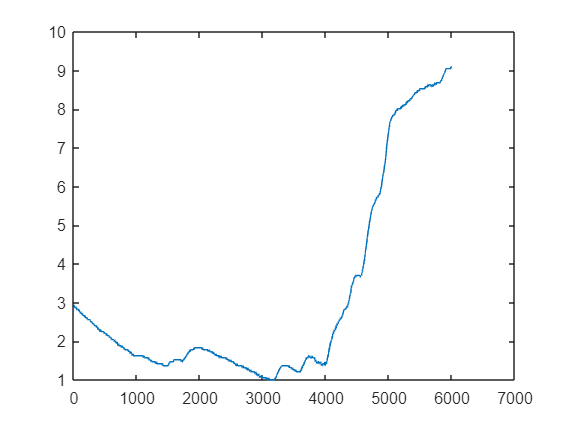


filter1 = Filter1_GSR;
y1 = filter(filter1,GSR_corrected);
filter2 = Filter2_GSR;
y2 = filter(filter2,y1);
plot(GSR_corrected)

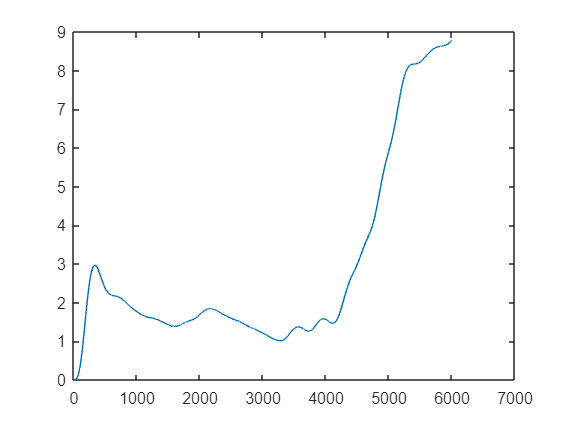

plot(y1)

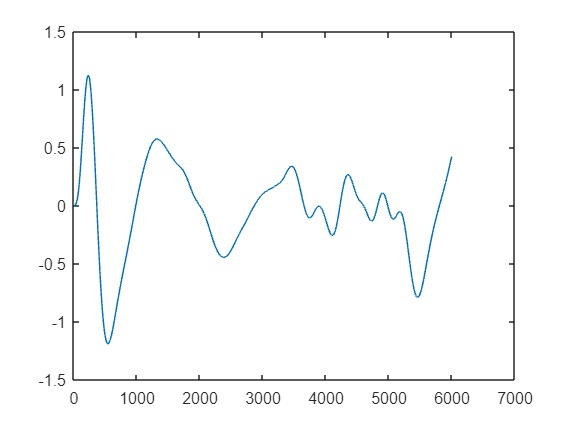

plot(y2)


fprintf('Nilai minimum setelah offset correction: %.2f μS\n', min(y2));

Nilai minimum setelah offset correction: -1.19 μS



%sample = uint32([1:size(y2)]);

num = 0;
onset = zeros(1,1);
offset = zeros(1,1);
peaks = zeros(1,1);

onset_flag = 0;
offset_flag = 0;
onset_val = 0;
offset_val = 0;
onset_idx = 0;
offset_idx = 0;
row_data = size(y2,1)

row_data = 6001

for i=1:row_data-1
    if (y2(i+1,1) - y2(i,1)) > 0  && y2(i,1) > 0.001 && onset_flag == 0
        onset_idx = i;
        onset_val = y2(i,1);
        onset_flag = 1;
        continue;
    end

    if (y2(i+1,1) - y2(i,1)) < 0 && y2(i,1) < 0 && offset_flag == 0 && onset_flag == 1
        offset_idx = i;
        offset_val = y2(i,1);
        onset_flag = 1;
    
        [pks,locs] = findpeaks(y2(onset_idx:offset_idx,1));
        if pks - onset_val > 0.03
            num = num+1;
            onset_flag = 0;
            offset_flag = 0;
            onset(num,1) = onset_val;
            onset(num,2) = onset_idx;
            offset(num,1) = offset_val;
            offset(num,2) = offset_idx;
            peaks(num,1) = pks;
            peaks(num,2) = onset_idx+locs-1;
        end
    end
end

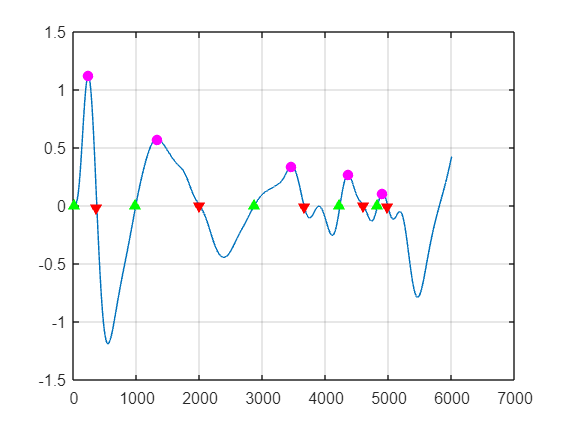

figure
plot(y2)
hold on
plot(onset(:,2), onset(:,1), '^g', 'MarkerFaceColor','g')
plot(offset(:,2), offset(:,1), 'vr', 'MarkerFaceColor','r')
plot(peaks(:,2), peaks(:,1), 'om', 'MarkerFaceColor','m')
hold off
grid

function Hd = Filter1_GSR
%FILTER1_GSR Returns a discrete-time filter object.

% MATLAB Code
% Generated by MATLAB(R) 9.13 and Signal Processing Toolbox 9.1.
% Generated on: 09-Oct-2024 23:25:04

% Chebyshev Type II Lowpass filter designed using FDESIGN.LOWPASS.

% All frequency values are in Hz.
    Fs = 100;  % Sampling Frequency
    
    N     = 4;    % Order
    Fstop = 1.5;  % Stopband Frequency
    Astop = 80;   % Stopband Attenuation (dB)
    
    % Construct an FDESIGN object and call its CHEBY2 method.
    h  = fdesign.lowpass('N,Fst,Ast', N, Fstop, Astop, Fs);
    Hd = design(h, 'cheby2');

% [EOF]
end


function Hd = Filter2_GSR
    %FILTER2_GSR Returns a discrete-time filter object.
    
    % MATLAB Code
    % Generated by MATLAB(R) 9.13 and Signal Processing Toolbox 9.1.
    % Generated on: 10-Oct-2024 00:36:19
    
    % Butterworth Highpass filter designed using FDESIGN.HIGHPASS.
    
    % All frequency values are in Hz.
    Fs = 100;  % Sampling Frequency
    
    N  = 4;     % Order
    Fc = 0.05;  % Cutoff Frequency
    
    % Construct an FDESIGN object and call its BUTTER method.
    h  = fdesign.highpass('N,F3dB', N, Fc, Fs);
    Hd = design(h, 'butter');

% [EOF]
end
